# Spectra for Pulse

Plots the complex line spectra for pulse with width T/w which repeats every T seconds.

## Parameters

A = 1;
w = 2;

## Fourier Series

[f,omega] = pulse_fs(A,w,15);

## Line Spectrum

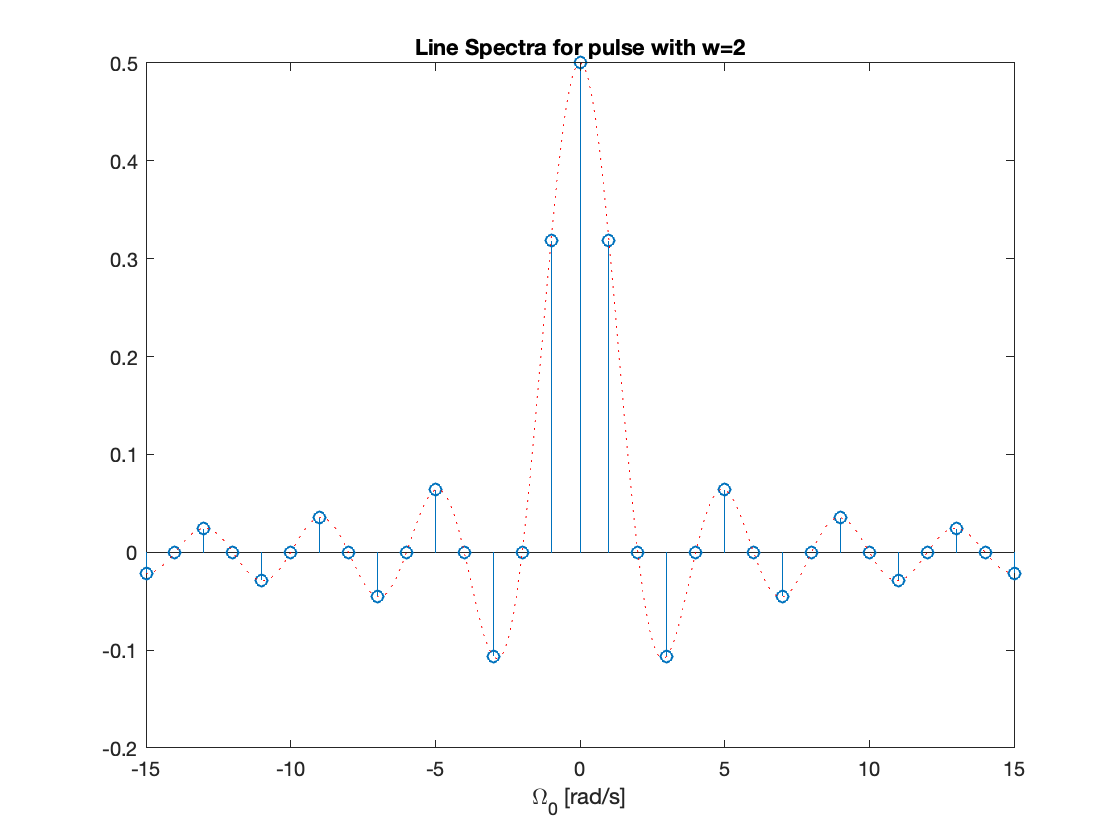

stem(omega,f)
title('Line Spectra for pulse with w=2')
hold on
om = linspace(-15,15,1000);
xlabel('\Omega_0 [rad/s]')
% add continuous sinc(x)/x envelope
xc = om.*pi./w;
plot(om,(A/w)*sin(xc)./(xc),'r:')
hold off

## Power spectrum

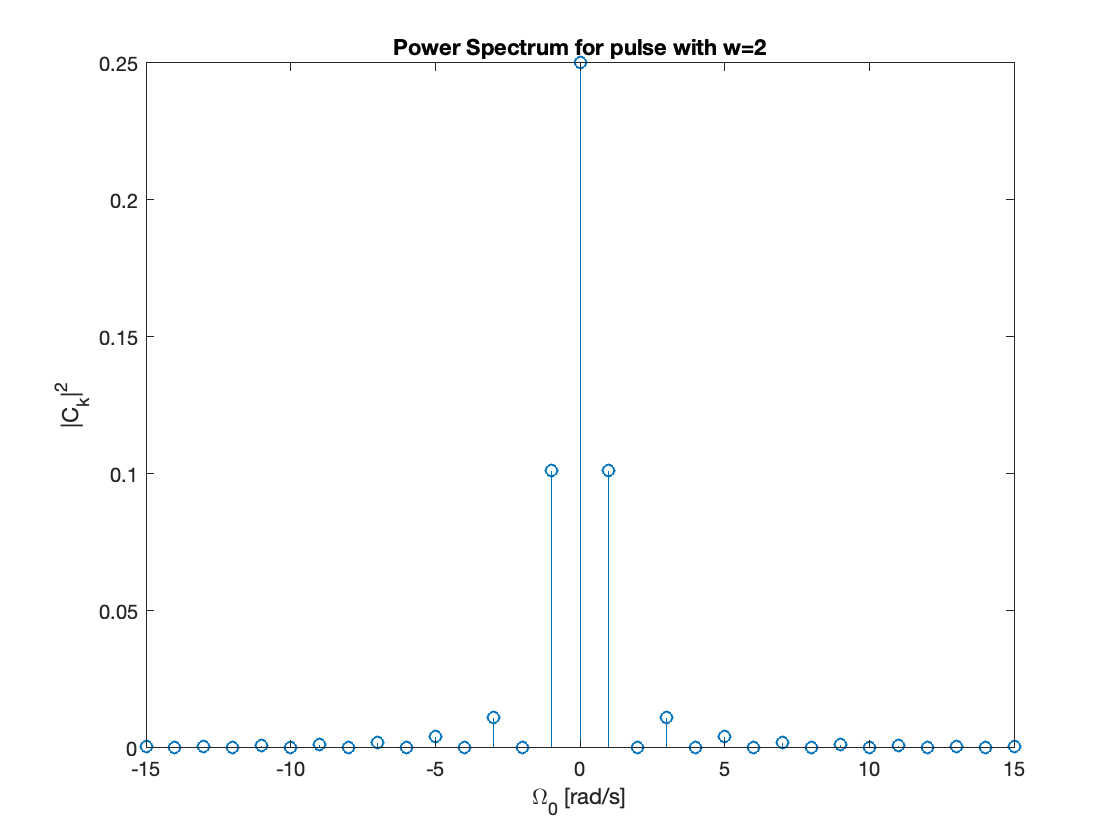

figure
stem(omega,f.^2)
title('Power Spectrum for pulse with w=2')
ylabel('|C_k|^2')
xlabel('\Omega_0 [rad/s]')